# Omission analysis

clear;clc;close all;

cd('D:\Electrophysiology\Matdelane\');
addpath(genpath('matnwb'));
addpath(genpath('matdelane'));
generateCore();

nwbPath = "data\";

nwbFiles = {dir(nwbPath).name};
nwbFiles = nwbFiles(endsWith(nwbFiles, ".nwb"));

disp("Toolbox setup done.");

Toolbox setup done.


I. Load all areas

nPath = "neuronData\";
nFiles = {dir(nPath).name};
nFiles = nFiles(endsWith(nFiles, ".mat"));

z = cell(1, 11);

for i = 1:11

    nFile = nFiles{i};
    z{i} = load(nPath + nFile).z;

end

Temporal PEV example (A vs. Random shuffle permutation)

cond1 = 4;
expvar = cell(1, 11);
ntotal = 0;
for k = 1:11
    for l = 1:size(z{k}{1}, 2)
        x1 = z{k}{cond1}{l}(:, :, randperm(5000, 5000));
        x2 = z{k}{cond1}{l}(:, :, 1:5000);
        
        N = min(size(x1, 1), size(x2, 1));
        n1 = size(x1, 2);
        ntotal = n1 + ntotal;
    
        idx1 = randperm(size(x1, 1), N);
        idx2 = randperm(size(x2, 1), N);
        
        x1 = squeeze(mean(x1(idx1, :, :)));
        x2 = squeeze(mean(x2(idx2, :, :)));
        
        data = [x2; x1];
        groupIDs = [ones(1, n1), ones(1, n1)*2];

        try

            data = jMeanFilt2(data, 1, 100);
            [expvar{k}(l, :), n, mu, p, F] = jPEV(data, groupIDs, 1);

        catch
        end

    end

end

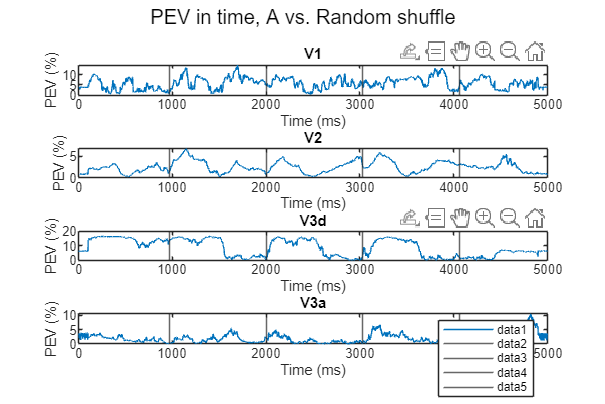

figure("Position", [0 0 1500 1000]);

for k = 1:4

    subplot(4, 1, k);
    plot(squeeze(mean(expvar{k}, 1))*100);

    xline(970);
    xline(2000);
    xline(3030);
    xline(4060);

    title(areaNames{k});
    xlabel("Time (ms)");
    ylabel("PEV (%)");

end

sgtitle("PEV in time, A vs. Random shuffle");

legend();

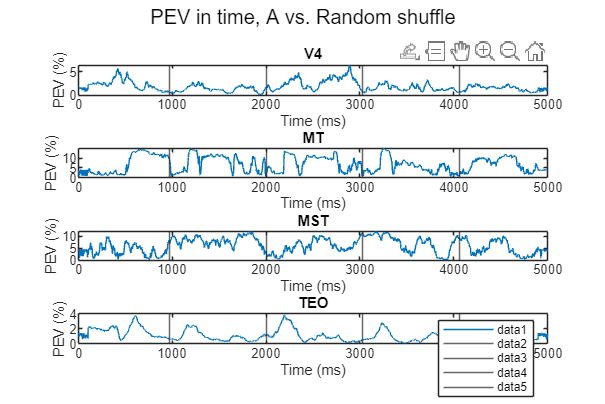

figure("Position", [0 0 1500 1000]);

for k = 5:8

    subplot(4, 1, k-4);
    plot(squeeze(mean(expvar{k}, 1))*100);
        
    xline(970);
    xline(2000);
    xline(3030);
    xline(4060);

    title(areaNames{k});
    xlabel("Time (ms)");
    ylabel("PEV (%)");

end

sgtitle("PEV in time, A vs. Random shuffle");

legend();

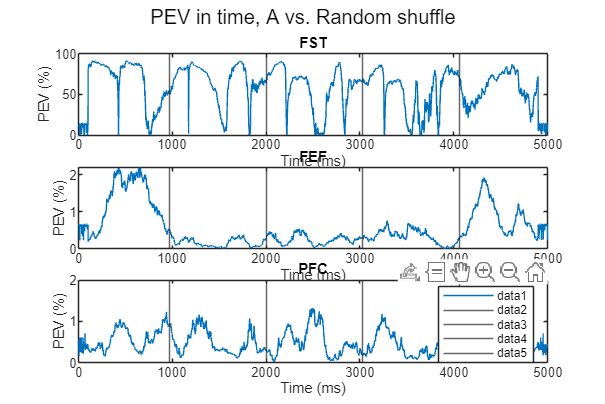

figure("Position", [0 0 1500 1000]);

for k = 9:11

    subplot(3, 1, k-8);
    plot(squeeze(mean(expvar{k}, 1))*100);

    xline(970);
    xline(2000);
    xline(3030);
    xline(4060);

    title(areaNames{k});
    xlabel("Time (ms)");
    ylabel("PEV (%)");

end

sgtitle("PEV in time, A vs. Random shuffle");

legend();

## I. Overal statistics (PEV, pVal < 0.001)

areaNames = cell(1, 11);
neuronCount = zeros(1, 11);
neuronSPEVcnt = zeros(1, 11);

for k = 1:11

    for l = 1:size(z{k}{1}, 2)
        x1 = z{k}{1}{l}(:, :, 501:1500);
        
        idx1 = randperm(size(x1, 1), min(100, size(x1, 1)));
        
        x1 = x1(idx1, :, :);
        data = squeeze(mean(x1, 1));
        try
            data = jMeanFilt2(data, 1, 20);
            groupIDs = [ones(1, 500), ones(1, 500)*2];
            [expVar, n, mu, p, F] = jPEV(data, groupIDs, 2);
    
            neuronCount(k) = neuronCount(k) + size(expVar, 1);
            neuronSPEVcnt(k) = neuronSPEVcnt(k) + sum(expVar > 0.05 & p < 0.005);
        catch
        end
    end

    areaName = strsplit(nFiles{k}, '_');
    areaNames{k} = areaName{end}(1:end-4);
end

neuronCount1 = neuronCount;
neuronSPEVcnt1 = neuronSPEVcnt;

neuronCount = zeros(1, 11);
neuronSPEVcnt = zeros(1, 11);
cond = 5;

for k = 1:11

    for l = 1:size(z{k}{cond}, 2)
        x1 = z{k}{cond}{l}(:, :, 501:1500);
        
        idx1 = randperm(size(x1, 1), min(100, size(x1, 1)));
        
        x1 = x1(idx1, :, :);
        data = squeeze(mean(x1, 1));
        try
            data = jMeanFilt2(data, 1, 20);
            groupIDs = [ones(1, 500), ones(1, 500)*2];
            [expVar, n, mu, p, F] = jPEV(data, groupIDs, 2);
    
            neuronCount(k) = neuronCount(k) + size(expVar, 1);
            neuronSPEVcnt(k) = neuronSPEVcnt(k) + sum(expVar > 0.05 & p < 0.005);
        catch
        end
    end

end

neuronCount2 = neuronCount;
neuronSPEVcnt2 = neuronSPEVcnt;

neuronCount = zeros(1, 11);
neuronSPEVcnt = zeros(1, 11);
cond = 9;

for k = 1:11

    for l = 1:size(z{k}{cond}, 2)
        x1 = z{k}{cond}{l}(:, :, 501:1500);
        
        idx1 = randperm(size(x1, 1), min(100, size(x1, 1)));
        
        x1 = x1(idx1, :, :);
        data = squeeze(mean(x1, 1));
        try
            data = jMeanFilt2(data, 1, 20);
            groupIDs = [ones(1, 500), ones(1, 500)*2];
            [expVar, n, mu, p, F] = jPEV(data, groupIDs, 2);
    
            neuronCount(k) = neuronCount(k) + size(expVar, 1);
            neuronSPEVcnt(k) = neuronSPEVcnt(k) + sum(expVar > 0.05 & p < 0.005);
        catch
        end
    end

end

neuronCount3 = neuronCount;
neuronSPEVcnt3 = neuronSPEVcnt;

neuronCount = zeros(1, 11);
neuronSPEVcnt = zeros(1, 11);
cond = 12;

for k = 1:11

    for l = 1:size(z{k}{cond}, 2)
        x1 = z{k}{cond}{l}(:, :, 3501:4500);
        
        idx1 = randperm(size(x1, 1), min(100, size(x1, 1)));
        
        x1 = x1(idx1, :, :);
        data = squeeze(mean(x1, 1));
        try
            data = jMeanFilt2(data, 1, 20);
            groupIDs = [ones(1, 500), ones(1, 500)*2];
            [expVar, n, mu, p, F] = jPEV(data, groupIDs, 2);
    
            neuronCount(k) = neuronCount(k) + size(expVar, 1);
            neuronSPEVcnt(k) = neuronSPEVcnt(k) + sum(expVar > 0.05 & p < 0.005);
        catch
        end
    end

end

neuronCount4 = neuronCount;
neuronSPEVcnt4 = neuronSPEVcnt;

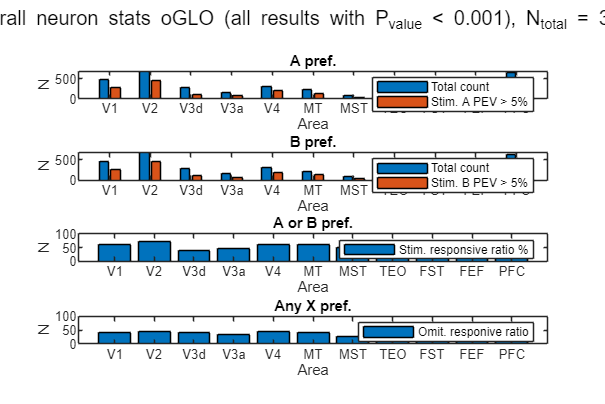

figure("Position", [0 0 1500 1000]);

subplot(4, 1, 1);
bar(areaNames, [neuronCount1; neuronSPEVcnt1]);
title("A pref.");
xlabel("Area");
ylabel("N");
legend("Total count", "Stim. A PEV > 5%");

subplot(4, 1, 2);
bar(areaNames, [neuronCount2; neuronSPEVcnt2]);
title("B pref.");
xlabel("Area");
ylabel("N");
legend("Total count", "Stim. B PEV > 5%");

subplot(4, 1, 3);
bar(areaNames, neuronSPEVcnt3./neuronCount3*100);
title("A or B pref.");
xlabel("Area");
ylabel("N");
ylim([0 100]);
legend("Stim. responsive ratio %");

subplot(4, 1, 4);
bar(areaNames, neuronSPEVcnt4./neuronCount4*100);
title("Any X pref.");
xlabel("Area");
ylabel("N");
ylim([0 100]);
legend("Omit. responive ratio");

sgtitle("Overall neuron stats oGLO (all results with P_{value} < 0.001), N_{total} = " + num2str(sum(neuronCount)));

## Conditional-comparative PEVs

PEV(A) ? PEV(B) ?PEV(R)

    Stimulus specific and non-specific preferences

(PEV(A),PEV(B),PEV(R)) ? PEV(X)

    Non-specific omission preferences

PEV(X|A) ? PEV(X|B) ? PEV(X|R)

    Specific omission preferences

neuronCount = zeros(1, 11);
neuronSPEVcnt = zeros(1, 11);
cond1 = 12;
cond2 = 9;

for k = 1:11

    for l = 1:size(z{k}{cond1}, 2)
        x1 = z{k}{cond1}{l}(:, :, 3501:4500);
        x2 = z{k}{cond2}{l}(:, :, 501:1500);
        
        idx1 = randperm(size(x1, 1), min(100, size(x1, 1)));
        idx2 = randperm(size(x2, 1), min(100, size(x2, 1)));
        
        x1 = x1(idx1, :, :);
        x2 = x2(idx2, :, :);

        data1 = squeeze(mean(x1, 1));
        data2 = squeeze(mean(x2, 1));

        % data1 = x1;
        % data2 = x2;

        try
            data1 = jMeanFilt2(data1, 1, 50);
            data2 = jMeanFilt2(data2, 1, 50);

            groupIDs = [ones(1, 500), ones(1, 500)*2];
            [expVar1, n, mu, p, F] = jPEV(data1, groupIDs, 3);
            [expVar2, n, mu, p, F] = jPEV(data2, groupIDs, 3);
    
            expVar1 = mean(expVar1, 1);
            expVar2 = mean(expVar2, 1);
            neuronCount(k) = neuronCount(k) + size(expVar1, 2);
            neuronSPEVcnt(k) = neuronSPEVcnt(k) + sum(expVar1 > 2*expVar2);
        catch
        end
    end

end

neuronCount5 = neuronCount;
neuronSPEVcnt5 = neuronSPEVcnt;

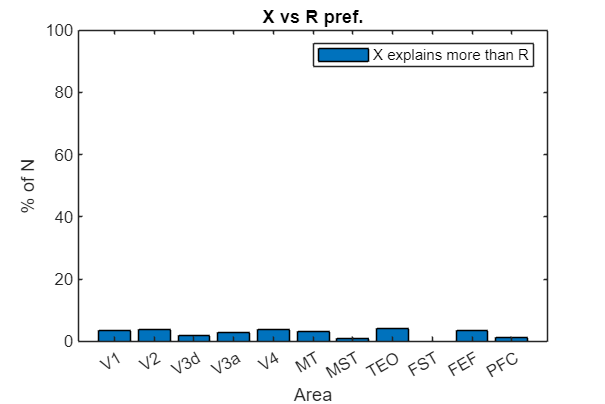

figure("Position", [0 0 1500 1000]);

% subplot(4, 1, 1);
% bar(areaNames, [neuronCount1; neuronSPEVcnt1]);
% title("A pref.");
% xlabel("Area");
% ylabel("N");
% legend("Total count", "Stim. A PEV > 5%");
% 
% subplot(4, 1, 2);
% bar(areaNames, [neuronCount2; neuronSPEVcnt2]);
% title("B pref.");
% xlabel("Area");
% ylabel("N");
% legend("Total count", "Stim. B PEV > 5%");
% 
% subplot(4, 1, 3);
% bar(areaNames, neuronSPEVcnt3./neuronCount3*100);
% title("A or B pref.");
% xlabel("Area");
% ylabel("N");
% ylim([0 100]);
% legend("Stim. responsive ratio %");

subplot(1, 1, 1);
bar(areaNames, neuronSPEVcnt5./neuronCount5*100);
title("X vs R pref.");
xlabel("Area");
ylabel("% of N");
ylim([0 100]);
legend("X explains more than R");

## Appendix

### A0. Identifiy areas

Nfile = numel(nwbFiles);
c = cell(1, Nfile);
x = cell(1, Nfile);

for k = 1:Nfile

    nwbFile = nwbPath + nwbFiles{k};
    nwb = nwbRead(nwbFile);
    [c{k}, x{k}] = jOGLOUnits(nwb, "omission_glo_passive", 1000, 5000);

end

% load("x.mat");load("c.mat");

### A1. Organize by area

areas = ["V1", "V2", "V3a", "V3d", "V4", "MT", "MST", "TEO", "FST", "FEF", "PFC"];
y = cell(11, 12);

for k = 1:numel(c)

    fprintf("%d-", k);
    for l = 1:numel(c{k})

        m = find(strcmpi(c{k}{l}.name, areas));
        
        try
    
            for j = 1:12
    
                sig = x{k}{j};
                y{m, j}{end + 1} = sig(:, c{k}{l}.ids, :);
    
            end

        catch

        end

    end

end

for i = 1:11

    cnt = 0;

    for j = 1:size(y{i, 1}, 2)

        cnt = cnt + size(y{i, 1}{j}, 2);

    end

    fprintf(areas(i) + " : %d\n", cnt);

end

for i = 1:11

    z = cell(1, 12);

    for j = 1:12
        z{j} = y{i, j};
    end

    save("neuronData\" + num2str(i) + "_Neurons_OGLO_" + areas(i), "z", "-v7.3");

end

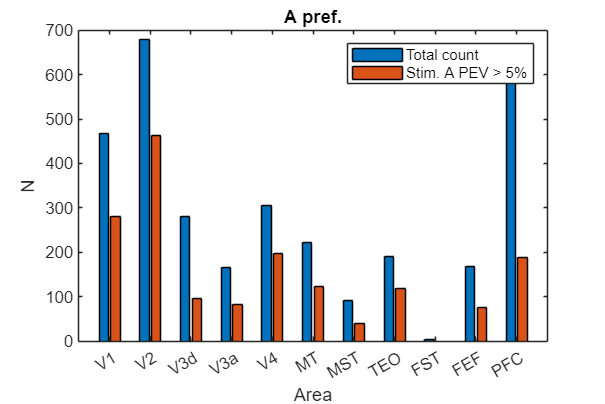

figure("Position", [0 0 1500 1000]);

subplot(1, 1, 1);
bar(areaNames, [neuronCount1; neuronSPEVcnt1]);
title("A pref.");
xlabel("Area");
ylabel("N");
legend("Total count", "Stim. A PEV > 5%");

## End